Después de un tiempo y de múltiples autorizaciones de seguridad, la empresa publica la estructura real del modelo de la planta ultra secreta. Su estructura es la siguiente


$$G\left(z\right)=z^{-1} \frac{1\ldotp 952\times {10}^{-5} z^5 +0\ldotp 001236z^4 +0\ldotp 002062z^3 -0\ldotp 002007z^2 -0\ldotp 0007909z-8\ldotp 798\times {10}^{-6} }{z^5 -3\ldotp 183z^4 +3\ldotp 77z^3 -1\ldotp 964z^2 +0\ldotp 3787z}$$


Además, comparte que **los datos suministrados al equipo fueron provenientes directamente del modelo no lineal **y que **el modelo no lineal no incluye retraso**. La empresa realiza una última petición opcional: analizar las discrepancias y sus causas entre el modelo real y el modelo estimado de la planta. Sin embargo, completar esta petición resultaría en una bonificación por parte de la empresa, por lo que el equipo acepta.

## Forma "canónica" del modelo real

Se observa que la expresión matemática del modelo real no concuerda con su forma canónica (potencias de $z$ negativas), por lo que lo primero que se hace es un poco de álgebra aplicada para llevarla a esta forma:


$$\begin{array}{l}
G\left(z\right)=\frac{1\ldotp 952\times {10}^{-5} z^5 +0\ldotp 001236z^4 +0\ldotp 002062z^3 -0\ldotp 002007z^2 -0\ldotp 0007909z-8\ldotp 798\times {10}^{-6} }{z^5 -3\ldotp 183z^4 +3\ldotp 77z^3 -1\ldotp 964z^2 +0\ldotp 3787z}\\
\;\;\;\;\;\;\;\;\;=\frac{\;z^{-5} }{z^{-5} }*\frac{1\ldotp 952\times {10}^{-5} z^5 +0\ldotp 001236z^4 +0\ldotp 002062z^3 -0\ldotp 002007z^2 -0\ldotp 0007909z-8\ldotp 798\times {10}^{-6} }{z^5 -3\ldotp 183z^4 +3\ldotp 77z^3 -1\ldotp 964z^2 +0\ldotp 3787z}\\
\;\;\;\;\;\;\;\;\;=\frac{1\ldotp 952\times {10}^{-5} +0\ldotp 001236z^{-1} +0\ldotp 002062z^{-2} -0\ldotp 002007z^{-3} -0\ldotp 0007909z^{-4} -8\ldotp 798\times {10}^{-6} z^{-5} }{1-3\ldotp 183z^{-1} +3\ldotp 77z^{-2} -1\ldotp 964z^{-3} +0\ldotp 3787z^{-4} }\\
\;\;\;\;\;\;\;\;\;=\frac{1\ldotp 952\times {10}^{-5} +0\ldotp 001236z^{-1} +0\ldotp 002062z^{-2} -0\ldotp 002007z^{-3} -0\ldotp 0007909z^{-4} -8\ldotp 798\times {10}^{-6} z^{-5} }{1-3\ldotp 183z^{-1} +3\ldotp 77z^{-2} -1\ldotp 964z^{-3} +0\ldotp 3787z^{-4} }
\end{array}$$


Ahora, considerando la expresión de un modelo ARX($na,nb,nk$)


$$y\left(t\right)=\frac{\;B\left(q\right)}{A\left(q\right)}u\left(t\right)+e\left(t\right)$$


donde$A\left(q\right)=1+a_1 q^{-1} +\ldotp \ldotp \ldotp +a_{na} q^{-na} ,$    $B\left(q\right)=b_1 q^{-nk} +\ldotp \ldotp \ldotp +b_{nb} q^{-\left(nk+nb-1\right)}$,    $nk\ge 0$, y recordando que la función de transferencia de un modelo ARX es de la forma $G\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}$, se deduce que la forma canónica del modelo real corresponde, de hecho, a la estructura de un modelo ARX($na=4,nb=6,nk=0$) o simplemente ARX(4,6,0). Note que el último término del numerador es $-8\ldotp 798\times {10}^{-6} z^{-5}$ y al tener un coeficiente en una escala tan pequeña, es posible simplificar el modelo a un ARX(4,5,0).

## **¿Será posible simplificar el modelo real ARX(4,6,0) con un ARX(4,5,0)?**

clear
load DataP1ModExp/data1f.mat % carga de datos

% Preprocesamiento
[data, train, test] = preprocessing_iddata(y, u, 1);
close % para no mostrar la figura train/test
[ARX_bestfit, ARX_AIC, ARX_MDL] = best_ARX(train, test, 4, 5:6, 0, 'arx')

ARX_bestfit =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                 
  A(z) = 1 - 3.264 z^-1 + 3.951 z^-2 - 2.096 z^-3 + 0.4091 z^-4                                     
                                                                                                    
  B(z) = 2.178e-09 + 0.001095 z^-1 + 0.002467 z^-2 - 0.002797 z^-3 - 0.0007132 z^-4 - 7.105e-06 z^-5
                                                                                                    
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=6   nk=0
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using PEM on time domain data "train". 
Fit to estimation data: 99.96% (prediction focus)
FPE: 1.367e-05, MSE: 1.287e-05                   

ARX_AIC =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                 

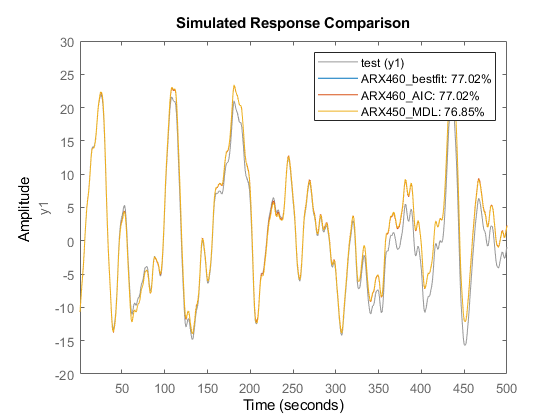

ARX460_bestfit = ARX_bestfit; ARX460_AIC = ARX_AIC;
ARX450_MDL = ARX_MDL;
compare(test, ARX460_bestfit, ARX460_AIC, ARX450_MDL)

Ambos modelos se comparan usando 3 criterios: mejor ajuste, AIC y MDL. El modelo ARX(4,6,0) fue mejor por el criterio de mejor ajueste y por el cirterio de información AIC; mientras que el modelo ARX(4,5,0) fue mejor por el criterio MDL y por parsimonia. Además, el ajuste de ambos modelos es aproximadamente el mismo: 77.02% para el ARX(4,6,0) y 76.85% para el ARX(4,5,0); por lo tanto, sí es posible simplificar el modelo real con un ARX(4,5,0). De aquí en adelante se tiene en cuenta el modelo simplificado ARX(4,5,0) para hacer comparaciones.

## Discrepancias y causas entre el modelo real y el modelo estimado

El modelo estimado en el último informe entregado corresponde a un modelo ARX(6,6,1) mientras que el modelo real de la planta corresponde a un ARX(4,6,0) o a un ARX(4,5,0) si se simplifica. Es claro que la estructura ARX del modelo estimado sí fue la adecuada, sin embargo, los parámetros estructurales ($na,\;nb,nk$) difieren al del modelo real y/o su modelo simplificado. Al comparar el ajuste de los modelos se obtiene lo siguiente

[ARX_bestfit, ARX_AIC, ARX_MDL] = best_ARX(train, test, [4,6], [5,6], [0,1], 'arx')

ARX_bestfit =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                     
  A(z) = 1 - 3.299 z^-1 + 4.257 z^-2 - 2.865 z^-3 + 1.249 z^-4 - 0.4219 z^-5 + 0.0797 z^-6              
                                                                                                        
  B(z) = 0.001095 z^-1 + 0.00243 z^-2 - 0.002671 z^-3 - 0.0001414 z^-4 - 0.0005289 z^-5 - 0.0001391 z^-6
                                                                                                        
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using PEM on time domain data "train". 
Fit to estimation data: 99.96% (prediction focus)
FPE: 1.328e-05, MSE: 1.236e-05                   

ARX_AIC =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e

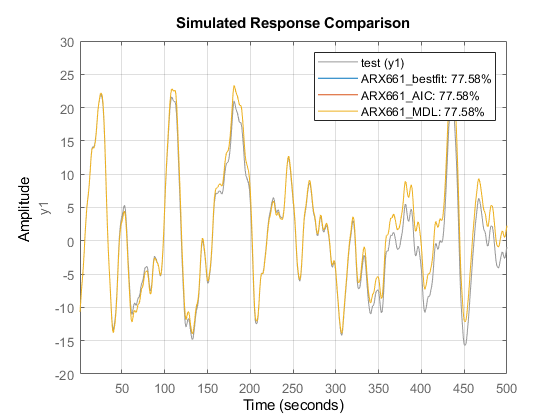

ARX661_bestfit = ARX_bestfit; ARX661_AIC = ARX_AIC; ARX661_MDL = ARX_MDL;
compare(test, ARX661_bestfit, ARX661_AIC, ARX661_MDL)
grid on

Al comparar el modelo estimado con el modelo real usando los 3 criterios anteriores, se observa que el modelo estimado es mejor en todos los 3 criterios, y que el modelo real es mejor únicamente respecto a la parsimonia. En cuanto al ajuste, el del modelo ARX(6,6,1) estimado es de 77.58%, el del modelo real ARX(4,6,0) es de 77.02% y el de su simplificación ARX(4,5,0) es de 76.85%.

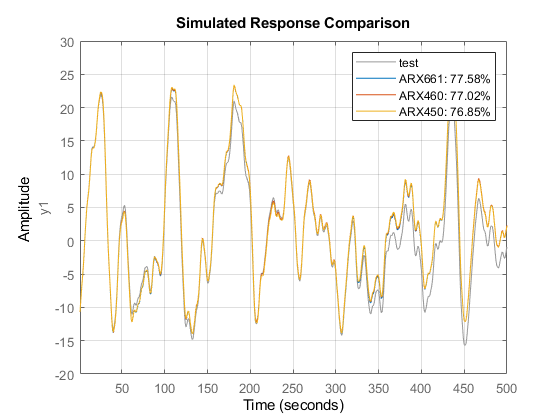

compare(test, ARX661_MDL, ARX460_AIC, ARX450_MDL)
legend('test', 'ARX661', 'ARX460', 'ARX450')
grid on;

La discrepencia en el retardo $nk$, presente en el modelo estimado ARX(6,6,1), se le atribuye a la información resultante del análisis de la secuencia de ponderación y a los resultados de los residuales que siempre sugerían la presencia de un retardo en 1, pero que aún al considerar dicho retardo de 1 los residuales de los modelos estimados nunca pasaban el test de blancura. Este comportamiento aún se observa en el modelo real ARX(4,6,0) y en su simplificación ARX(4,5,0).

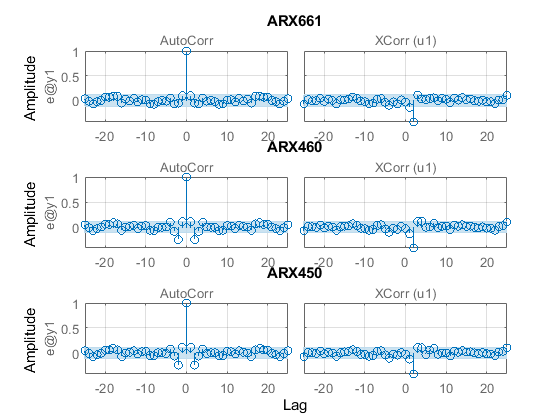

clf
subplot(3,1,1); resid(test, ARX661_MDL); grid on; title('ARX661'); xlabel('');
subplot(3,1,2); resid(test, ARX460_AIC); grid on; title('ARX460'); xlabel('');
subplot(3,1,3); resid(test, ARX450_MDL); grid on; title('ARX450');

El hecho de que este comportamiento no deseado persista en el modelo ARX que supuestamente mejor representa al modelo real de la planta, valida el hecho de que aún con un modelo mejor modelo ARX, como es el caso del modelo estimado, los resultados fueran similares.

La discrepancia en el número de rezagos sobre la entrada $nb$ únicamente ocurre si se compara el modelo estimado ARX(6,6,1) con el modelo real simplificado ARX(4,5,0), por lo que no se considera muy relevante, pues técnicamente coincidió con el modelo real ARX(4,6,0).

Finalmente, la discrepancia en el número de rezagos sobre la salida $na$ fue clara entre el modelo estimado y el modelo real, donde el modelo estimado presentó un mayor valor y tanto el modelo estimado como su simplificación presentaron el mismo valor menor que el estimado. Un aspecto importante a resaltar es que únicamente el modelo estimado ARX(6,6,1) cumple la condición $na>nb-nk$, que es una condición necesaria y recomendada al momento de la identificación del modelo para tener una modelación adecuada de la entrada/salida.